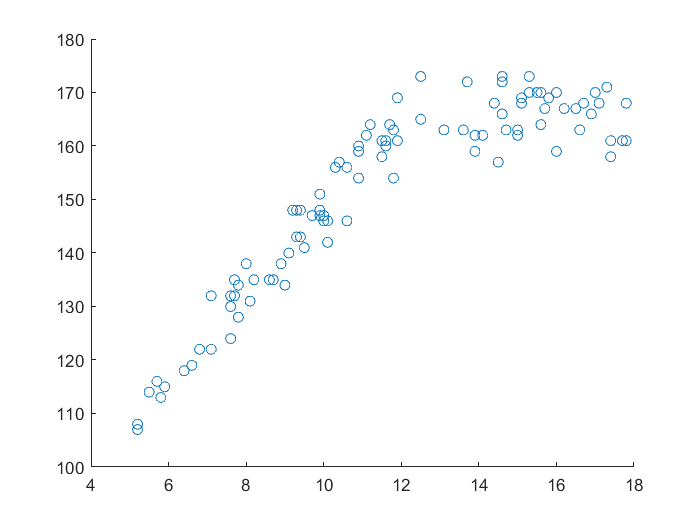

data=readtable("height_of_girls.txt");
X=table2array(data(:,"Age"));
Y=table2array(data(:,"Height"));
scatter(X,Y)

f = @(x) (x<12).*(x-12)

f = function_handle with value:
    @(x)(x<12).*(x-12)


g = @(x) ones(size(x))

g = function_handle with value:
    @(x)ones(size(x))


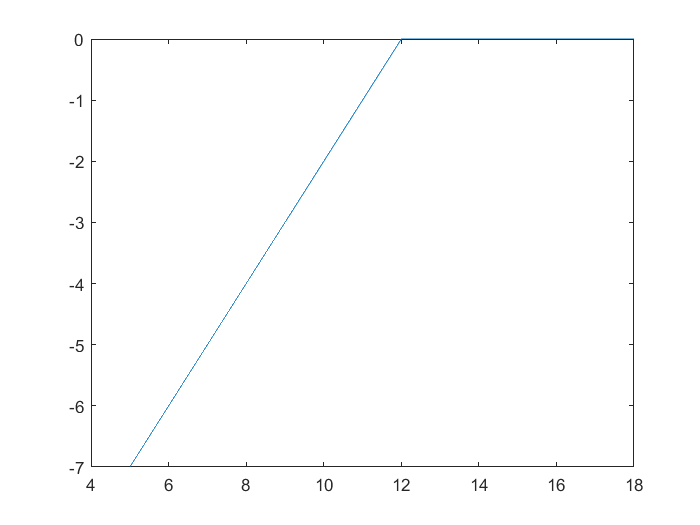

XX=5:0.01:18;
plot(XX,f(XX))

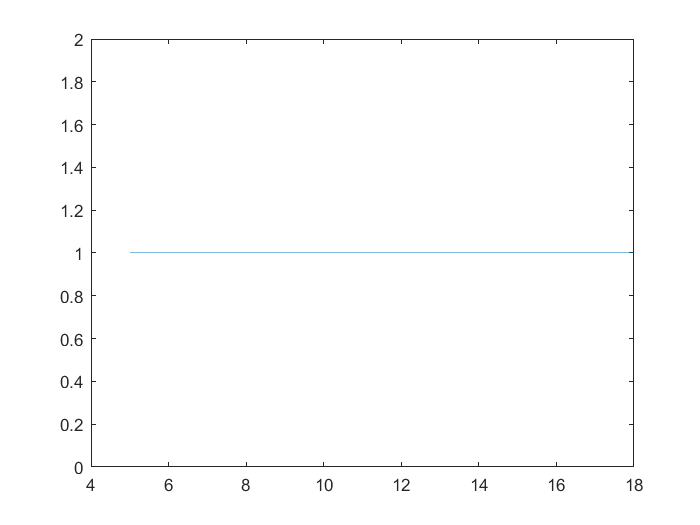

plot(XX,g(XX))

A=[f(X),g(X)];
c=A\Y

c =     8.2811
  165.5820


h=@(x) c(1)*f(x)+c(2)*g(x);
YY=h(XX)

YY =   107.6141  107.6969  107.7797  107.8625  107.9454  108.0282  108.1110  108.1938  108.2766  108.3594  108.4422  108.5250  108.6078  108.6907  108.7735  108.8563  108.9391  109.0219  109.1047  109.1875  109.2703  109.3531  109.4360  109.5188  109.6016  109.6844  109.7672  109.8500  109.9328  110.0156  110.0984  110.1813  110.2641  110.3469  110.4297  110.5125  110.5953  110.6781  110.7609  110.8437  110.9266  111.0094  111.0922  111.1750  111.2578  111.3406  111.4234  111.5062  111.5890  111.6719


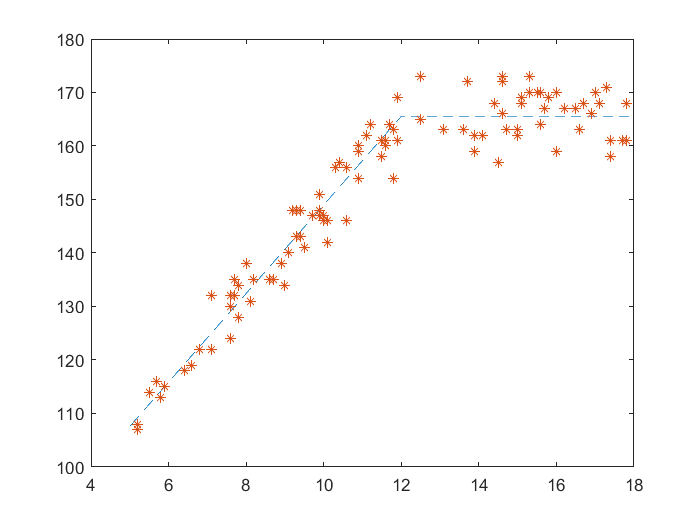

plot(XX,YY,'--',X,Y,'*')

h(12)

ans = 165.5820

h(5)

ans = 107.6141